clear;
load("Data\data_all.mat");
class_labels=0:9;

M = 2048; % Antall grupper
num_classes=10;
C = []; % Gruppesentrum matrise
C_labels = repelem(0:num_classes-1, M)';

tic; % Start tid
for i = 1:num_classes
    trainvi = trainv(trainlab == (i - 1), :); 
    [~, Ci] = kmeans(trainvi, M);
    C = [C; Ci];
end

K = 1; % Antall naboer som brukes til referanse
predicted_labels_knn = knn_classifier(C, C_labels, testv, K);
conf_matrix_knn = confusionmat(testlab, predicted_labels_knn);
error_rate_knn = 1 - sum(diag(conf_matrix_knn)) / sum(conf_matrix_knn(:));

tid=toc; % Slutt tid
time_str = datestr(seconds(tid), 'HH:MM:SS');

fprintf('Training time: %s\n', time_str);

Training time: 00:00:37


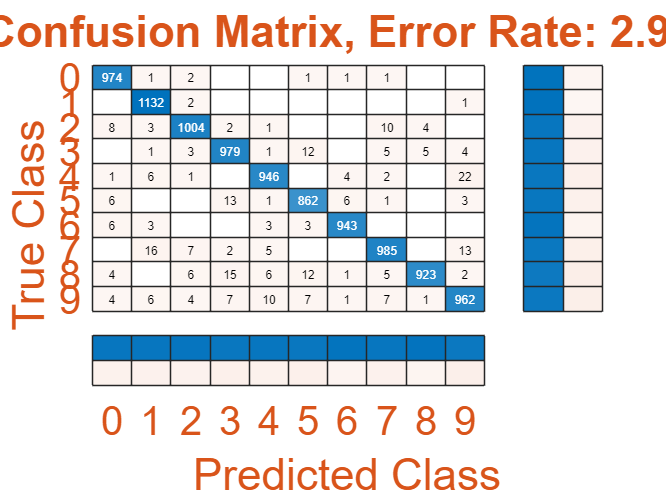

figure;
confusionchart(conf_matrix_knn, class_labels,'FontColor','0.85,0.33,0.10','FontSize',24,'RowSummary','row-normalized','ColumnSummary','column-normalized');
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate_knn * 100,2)), '%']);